%% BICYCLE MODEL PERFORMANCE ANALYSIS WITH RRT* TRAJECTORY
% Comprehensive analysis of Bicycle Model controller performance
% This script generates publication-quality plots for controller evaluation

%% SETUP AND CONFIGURATION
fprintf('=== BICYCLE MODEL PERFORMANCE ANALYSIS ===\n');

=== BICYCLE MODEL PERFORMANCE ANALYSIS ===



% Verify required variables
required_vars = {'vehicle_state', 'vehicle_velocity', 'reference_trajectory', ...
                'reference_velocity', 'velocity_command', 'steering_command', ...
                'time_vector', 'curr_theta', 'acc_cmd','dece_cmd'};
missing_vars = {};
for i = 1:length(required_vars)
    if ~exist(required_vars{i}, 'var')
        missing_vars{end+1} = required_vars{i};
    end
end

if ~isempty(missing_vars)
    fprintf('ERROR: Run Simulink simulation first!\n');
    fprintf('Missing variables:\n');
    for i = 1:length(missing_vars)
        fprintf('  - %s\n', missing_vars{i});
    end
    return;
end

% Configure LaTeX interpreter and plot styling - professional academic style
set(0, 'defaultTextInterpreter', 'latex');
set(0, 'defaultAxesTickLabelInterpreter', 'latex');
set(0, 'defaultLegendInterpreter', 'latex');

fontSize = 14;
titleSize = 16;
legendSize = 12;
lineWidth = 2;

% Define color palette
color_red = [0.8, 0.2, 0.2];      % Red for actual/errors
color_yellow = [0.8, 0.6, 0.2];   % Dark yellow for desired/reference
color_blue = [0.2, 0.3, 0.8];     % Dark blue for commands/analysis

% Create figure directory if it doesn't exist
if ~exist('figures', 'dir')
    mkdir('figures');
end

%% DATA PREPROCESSING
fprintf('Preprocessing timeseries data...\n');

Preprocessing timeseries data...



% Extract data from timeseries objects
[time_actual, state_data] = extractAndSyncTimeseries(vehicle_state, 'vehicle_state');

actual_x = state_data(:,1);
actual_y = state_data(:,2);
actual_theta = state_data(:,3);

[time_ref, ref_traj_data] = extractAndSyncTimeseries(reference_trajectory, 'reference_trajectory');

ref_x = ref_traj_data(:,1);
ref_y = ref_traj_data(:,2);
ref_theta = ref_traj_data(:,3);

[time_actual_vel, velocity_data] = extractAndSyncTimeseries(vehicle_velocity, 'vehicle_velocity');
actual_linear_vel = velocity_data(:,1);

[time_ref_vel, ref_velocity_data] = extractAndSyncTimeseries(reference_velocity, 'reference_velocity');
ref_linear_vel = ref_velocity_data(:,1);

[time_v_cmd, data_v_cmd] = extractAndSyncTimeseries(velocity_command, 'velocity_command');
[time_phi_cmd, data_phi_cmd] = extractAndSyncTimeseries(steering_command, 'steering_command');
[time_acc_cmd, data_acc_cmd] = extractAndSyncTimeseries(acc_cmd, 'acc_cmd');
[time_dece_cmd, data_dece_cmd] = extractAndSyncTimeseries(dece_cmd, 'dece_cmd');

% Determine actual simulation duration
actual_sim_duration = time_actual(end);
fprintf('Data extracted. Simulation duration: %.2f s\n', actual_sim_duration);

Data extracted. Simulation duration: 87.30 s



%% 1. TRAJECTORY TRACKING PERFORMANCE WITH MAP VISUALIZATION
fprintf('Generating trajectory tracking visualization with bicycle...\n');

Generating trajectory tracking visualization with bicycle...


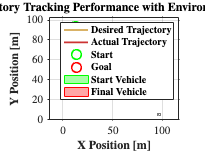


figure('Name', 'Trajectory Tracking', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);

% Plot cost map
if exist('costmap', 'var')
    plot(costmap, 'Inflation', 'off');
end
hold on;

% Plot desired trajectory
plot(ref_x, ref_y, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Desired Trajectory}');

% Plot actual trajectory
plot(actual_x, actual_y, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Trajectory}');

% Determine start and goal positions
if exist('routePlan', 'var')
    initialPose = routePlan{1, 'StartPose'};
    finalGoal = routePlan{end, 'EndPose'};
else
    initialPose = [ref_x(1), ref_y(1), ref_theta(1)];
    finalGoal = [ref_x(end), ref_y(end), ref_theta(end)];
end

% Plot start and goal positions
plot(initialPose(1), initialPose(2), 'go', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', '\textbf{Start}');
plot(finalGoal(1), finalGoal(2), 'ro', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', '\textbf{Goal}');

% Add vehicle representation at key points
vehicleDims = [];
if exist('costmap', 'var') && isprop(costmap, 'CollisionChecker')
    vehicleDims = costmap.CollisionChecker.VehicleDimensions;
end

% Plot vehicles at start and final positions
PlotBicycle(initialPose, vehicleDims, 0, 'Color', 'g', 'DisplayName', '\textbf{Start Vehicle}');
PlotBicycle([actual_x(end), actual_y(end), actual_theta(end)], vehicleDims, 0, ...
           'Color', 'r', 'DisplayName', '\textbf{Final Vehicle}');

% Set labels, title and legend with LaTeX formatting
xlabel('\textbf{X Position [m]}', 'FontSize', fontSize);
ylabel('\textbf{Y Position [m]}', 'FontSize', fontSize);
title('\textbf{Trajectory Tracking Performance with Environment Map}', 'FontSize', titleSize);

% Set axis limits and legend position
legend('Location', 'northeast', 'FontSize', legendSize);

% Final axis settings
axis equal;
grid on;
hold off;
set(gca, 'FontSize', fontSize);

% Save figure
saveas(gcf, 'figures/trajectory_tracking_bicycle.eps', 'epsc');


%% 2. STATE VARIABLES TRACKING COMPARISON
fprintf('Generating state variables comparison...\n');

Generating state variables comparison...


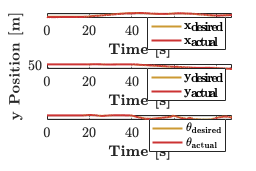

figure('Position', [150, 150, 1200, 800]);

% X position tracking
subplot(3, 1, 1);
plot(time_ref, ref_x, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{x_{desired}}$');
hold on;
plot(time_actual, actual_x, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{x_{actual}}$');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{x Position [m]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Y position tracking
subplot(3, 1, 2);
plot(time_ref, ref_y, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{y_{desired}}$');
hold on;
plot(time_actual, actual_y, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{y_{actual}}$');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{y Position [m]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Heading tracking 
subplot(3, 1, 3);

ref_theta_cumulative = unwrap(ref_theta);
actual_theta_cumulative = unwrap(actual_theta);

ref_rotations = ref_theta_cumulative / (2*pi);
actual_rotations = actual_theta_cumulative / (2*pi);

plot(time_ref, ref_rotations, 'Color', color_yellow, 'LineWidth', lineWidth, ...
     'DisplayName', '$\mathbf{\theta_{desired}}$');
hold on;
plot(time_actual, actual_rotations, 'Color', color_red, 'LineWidth', lineWidth, ...
     'DisplayName', '$$\mathbf{\theta_{actual}}$');

xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Heading angle [rad]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/state_variables_tracking_bicycle.eps', 'epsc');


%% 3. TRACKING ERRORS ANALYSIS
fprintf('Generating tracking errors analysis...\n');

Generating tracking errors analysis...


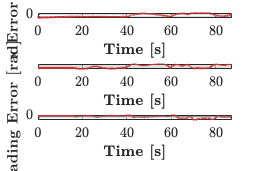


% Interpolate reference values at actual time points
ref_x_interp = interp1(time_ref, ref_x, time_actual, 'linear', 'extrap');
ref_y_interp = interp1(time_ref, ref_y, time_actual, 'linear', 'extrap');
ref_theta_interp = interp1(time_ref, ref_theta, time_actual, 'linear', 'extrap');

% Force vectors to be columns
actual_theta = actual_theta(:);
ref_theta_interp = ref_theta_interp(:);

% Calculate errors
x_error = actual_x - ref_x_interp;
y_error = actual_y - ref_y_interp;

% Calculate theta error with wrapping to [-pi, pi]
ref_theta_wrapped = wrapToPi(ref_theta_interp);
actual_theta_wrapped = wrapToPi(actual_theta);

theta_error = zeros(size(actual_theta_wrapped));
for i = 1:length(theta_error)
    diff = actual_theta_wrapped(i) - ref_theta_wrapped(i);
    theta_error(i) = wrapToPi(diff);
end

ref_theta_cumulative = unwrap(ref_theta_interp);
actual_theta_cumulative = unwrap(actual_theta);

theta_error_cumulative = actual_theta_cumulative - ref_theta_cumulative;

rotation_error = theta_error_cumulative / (2*pi);

% Calculate Euclidean error
euclidean_error = sqrt(x_error.^2 + y_error.^2);

figure('Position', [100, 100, 1200, 800]);

% Plot X error
subplot(3, 1, 1);
plot(time_actual, x_error, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{x Error [m]}', 'FontSize', fontSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Plot Y error
subplot(3, 1, 2);
plot(time_actual, y_error, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{y Error [m]}', 'FontSize', fontSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Plot theta error
subplot(3, 1, 3);
plot(time_actual, rotation_error, 'Color', color_red, 'LineWidth', lineWidth);
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Heading Error [rad]}', 'FontSize', fontSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/tracking_errors_bicycle.eps', 'epsc');


%% 4. CONTROL COMMANDS ANALYSIS
fprintf('Generating control commands analysis...\n');

Generating control commands analysis...


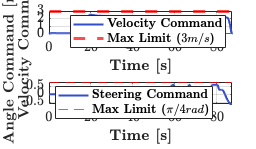

figure('Position', [250, 250, 1200, 700]);

% Velocity command
subplot(2, 1, 1);
plot(time_v_cmd, data_v_cmd, 'Color', color_blue, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Velocity Command}');
hold on;
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5, 'HandleVisibility', 'off');
v_max = 3;
yline(v_max, '--r', 'LineWidth', 3, 'DisplayName', '\textbf{Max Limit ($3 m/s$)}');

xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Velocity Command [m/s]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
grid on;
xlim([0, actual_sim_duration]);
set(gca, 'FontSize', fontSize);

% Steering command - MODIFICA 2: Legend at southwest and add dashed lines
subplot(2, 1, 2);
% Plot steering command
plot(time_phi_cmd, data_phi_cmd, 'Color', color_blue, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Steering Command}');
hold on;
%yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5, 'HandleVisibility', 'off');
phi_max = pi/4;
yline(phi_max, '--r', 'LineWidth', 0.785, 'DisplayName', '\textbf{Max Limit ($\pi/4 rad$)}');

xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Steering Angle Command [rad]}', 'FontSize', fontSize);
legend('Location', 'southwest', 'FontSize', legendSize);  % CHANGED TO SOUTHWEST
grid on;
xlim([0, actual_sim_duration]);
set(gca, 'FontSize', fontSize);


saveas(gcf, 'figures/control_commands_bicycle.eps', 'epsc');


%% 5. VELOCITY TRACKING AND ERRORS
fprintf('Generating velocity tracking analysis...\n');

Generating velocity tracking analysis...


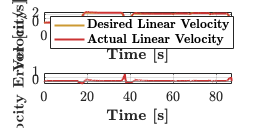


figure('Position', [300, 300, 1200, 600]);

% Linear velocity tracking
subplot(2, 1, 1);
plot(time_ref_vel, ref_linear_vel, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Desired Linear Velocity}');
hold on;
plot(time_actual_vel, actual_linear_vel, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Linear Velocity}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Velocity [m/s]}', 'FontSize', fontSize);
legend('Location', 'southwest', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Velocity error
subplot(2, 1, 2);
ref_vel_interp = interp1(time_ref_vel, ref_linear_vel, time_actual_vel, 'linear', 'extrap');
velocity_error = actual_linear_vel - ref_vel_interp;
plot(time_actual_vel, velocity_error, 'Color', color_red, 'LineWidth', lineWidth);
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Velocity Error [m/s]}', 'FontSize', fontSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/velocity_tracking_bicycle.eps', 'epsc');


%% 6. EUCLIDEAN ERROR OVER TIME
fprintf('Generating Euclidean error plot...\n');

Generating Euclidean error plot...


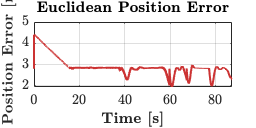

figure('Position', [350, 350, 800, 400]);

plot(time_actual, euclidean_error, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Position Error [m]}', 'FontSize', fontSize);
title('\textbf{Euclidean Position Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Add settling time marker if applicable
settling_threshold = 0.5;
settling_idx = find(euclidean_error < settling_threshold, 1, 'last');
if ~isempty(settling_idx)
    hold on;
    xline(time_actual(settling_idx), '--g', 'LineWidth', 1.5);
    text(time_actual(settling_idx), max(euclidean_error)*0.8,...
         sprintf('\\textbf{Settling time: %.1f s}', time_actual(settling_idx)),...
         'FontSize', fontSize-2, 'BackgroundColor', 'white');
end

saveas(gcf, 'figures/euclidean_error_bicycle.eps', 'epsc');


%% 7. ACCELERATION/DECELERATION ANALYSIS - MODIFICA 3: Fixed to show acc_cmd and dece_cmd
fprintf('Generating acceleration analysis...\n');

Generating acceleration analysis...


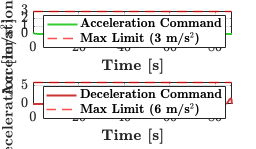

figure('Position', [400, 400, 1200, 700]);

% Acceleration limits
acc_max = 3; % m/s^2
dec_max = 6; % m/s^2

% Plot acceleration
subplot(2, 1, 1);
plot(time_acc_cmd, data_acc_cmd, 'Color', [0.2 0.8 0.2], 'LineWidth', lineWidth, 'DisplayName', '\textbf{Acceleration Command}');
hold on;
yline(acc_max, '--r', 'LineWidth', 1.5, 'DisplayName', '\textbf{Max Limit (3 m/s$^2$)}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Acceleration [m/s$^2$]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Plot deceleration
subplot(2, 1, 2);
plot(time_dece_cmd, data_dece_cmd, 'Color', [0.8 0.2 0.2], 'LineWidth', lineWidth, 'DisplayName', '\textbf{Deceleration Command}');
hold on;
yline(dec_max, '--r', 'LineWidth', 1.5, 'DisplayName', '\textbf{Max Limit (6 m/s$^2$)}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Deceleration [m/s$^2$]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/acceleration_analysis_bicycle.eps', 'epsc');


%% 8. LINEAR AND ANGULAR VELOCITY TRACKING - MODIFICA 4: New figure
fprintf('Generating linear and angular velocity tracking...\n');

Generating linear and angular velocity tracking...


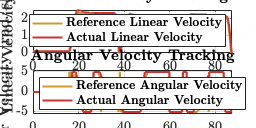


% Calculate angular velocities from theta derivatives with unwrapping
% Unwrap angles to avoid discontinuities
ref_theta_unwrapped = unwrap(ref_theta);
actual_theta_unwrapped = unwrap(actual_theta);

% Calculate angular velocities using central differences for better accuracy
ref_angular_vel = zeros(size(ref_theta));
actual_angular_vel = zeros(size(actual_theta));

% Use central differences for interior points
for i = 2:length(ref_theta)-1
    ref_angular_vel(i) = (ref_theta_unwrapped(i+1) - ref_theta_unwrapped(i-1)) / (time_ref(i+1) - time_ref(i-1));
end
% Use forward/backward differences for endpoints
ref_angular_vel(1) = (ref_theta_unwrapped(2) - ref_theta_unwrapped(1)) / (time_ref(2) - time_ref(1));
ref_angular_vel(end) = (ref_theta_unwrapped(end) - ref_theta_unwrapped(end-1)) / (time_ref(end) - time_ref(end-1));

% Same for actual angular velocity
for i = 2:length(actual_theta)-1
    actual_angular_vel(i) = (actual_theta_unwrapped(i+1) - actual_theta_unwrapped(i-1)) / (time_actual(i+1) - time_actual(i-1));
end
actual_angular_vel(1) = (actual_theta_unwrapped(2) - actual_theta_unwrapped(1)) / (time_actual(2) - time_actual(1));
actual_angular_vel(end) = (actual_theta_unwrapped(end) - actual_theta_unwrapped(end-1)) / (time_actual(end) - time_actual(end-1));

% Apply more aggressive filtering to reference angular velocity to handle planning artifacts
window_size_ref = 15; % Larger window for reference to smooth planning discontinuities
window_size_actual = 5; % Smaller window for actual to preserve dynamics

if length(ref_angular_vel) > window_size_ref
    ref_angular_vel = movmean(ref_angular_vel, window_size_ref);
end
if length(actual_angular_vel) > window_size_actual
    actual_angular_vel = movmean(actual_angular_vel, window_size_actual);
end

% Limit extreme values (saturation at reasonable angular velocity limits)
max_angular_vel = 5; % rad/s - reasonable limit for a vehicle
ref_angular_vel = max(min(ref_angular_vel, max_angular_vel), -max_angular_vel);
actual_angular_vel = max(min(actual_angular_vel, max_angular_vel), -max_angular_vel);

figure('Position', [450, 450, 1200, 600]);

% Linear velocity subplot
subplot(2, 1, 1);
plot(time_ref_vel, ref_linear_vel, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Reference Linear Velocity}');
hold on;
plot(time_actual_vel, actual_linear_vel, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Linear Velocity}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Linear Velocity [m/s]}', 'FontSize', fontSize);
title('\textbf{Linear Velocity Tracking}', 'FontSize', titleSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Angular velocity subplot
subplot(2, 1, 2);
plot(time_ref, ref_angular_vel, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Reference Angular Velocity}');
hold on;
plot(time_actual, actual_angular_vel, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Angular Velocity}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Angular Velocity [rad/s]}', 'FontSize', fontSize);
title('\textbf{Angular Velocity Tracking}', 'FontSize', titleSize);
legend('Location', 'southwest', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
ylim([-max_angular_vel*1.1, max_angular_vel*1.1]); % Set y-axis limits
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/velocity_tracking_linear_angular_bicycle.eps', 'epsc');


%% 9. LINEAR AND ANGULAR VELOCITY ERRORS 
fprintf('Generating linear and angular velocity errors...\n');

Generating linear and angular velocity errors...


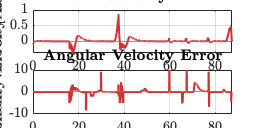


% Calculate linear velocity error
ref_vel_interp = interp1(time_ref_vel, ref_linear_vel, time_actual_vel, 'linear', 'extrap');
linear_velocity_error = actual_linear_vel - ref_vel_interp;

% Angular velocities are already calculated in section 8
% Calculate angular velocity error
ref_angular_vel_interp = interp1(time_ref, ref_angular_vel, time_actual, 'linear', 'extrap');
angular_velocity_error = actual_angular_vel - ref_angular_vel_interp;

figure('Position', [500, 500, 1200, 600]);

% Linear velocity error subplot
subplot(2, 1, 1);
plot(time_actual_vel, linear_velocity_error, 'Color', color_red, 'LineWidth', lineWidth);
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Linear Velocity Error [m/s]}', 'FontSize', fontSize);
title('\textbf{Linear Velocity Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Angular velocity error subplot
subplot(2, 1, 2);
plot(time_actual, angular_velocity_error, 'Color', color_red, 'LineWidth', lineWidth);
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Angular Velocity Error [rad/s]}', 'FontSize', fontSize);
title('\textbf{Angular Velocity Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/velocity_errors_linear_angular_bicycle.eps', 'epsc');



fprintf('Generating KPI summary plot...\n');

Generating KPI summary plot...


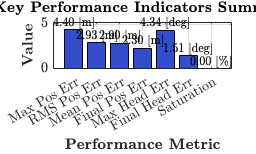


% Calculate KPIs
kpi_max_pos_err = max(euclidean_error);
kpi_rms_pos_err = rms(euclidean_error);
kpi_mean_pos_err = mean(euclidean_error);
kpi_final_pos_err = euclidean_error(end);
kpi_max_heading_err = max(abs(rotation_error));
kpi_final_heading_err = abs(rotation_error(end));
saturation_percentage = sum(abs(data_phi_cmd) > phi_max*0.95) / length(data_phi_cmd) * 100;
kpi_saturation = saturation_percentage;

figure('Position', [550, 550, 1000, 600]);

% Create KPI names and values
kpi_names = categorical({'Max Pos Err', 'RMS Pos Err', 'Mean Pos Err', 'Final Pos Err', ...
                        'Max Head Err', 'Final Head Err', 'Saturation'});
kpi_names = reordercats(kpi_names, {'Max Pos Err', 'RMS Pos Err', 'Mean Pos Err', 'Final Pos Err', ...
                                    'Max Head Err', 'Final Head Err', 'Saturation'});
kpi_values = [kpi_max_pos_err, kpi_rms_pos_err, kpi_mean_pos_err, kpi_final_pos_err, ...
              kpi_max_heading_err, kpi_final_heading_err, kpi_saturation];
kpi_units = {'[m]', '[m]', '[m]', '[m]', '[deg]', '[deg]', '[\%]'};

% Create bar plot
bar_plot = bar(kpi_names, kpi_values, 'FaceColor', color_blue);

% Add value labels on bars
xtips = bar_plot.XEndPoints;
ytips = bar_plot.YEndPoints;
for i = 1:length(ytips)
    text(xtips(i), ytips(i), sprintf('%.2f %s', kpi_values(i), kpi_units{i}), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', fontSize-2, 'FontWeight', 'bold');
end

xlabel('\textbf{Performance Metric}', 'FontSize', fontSize);
ylabel('\textbf{Value}', 'FontSize', fontSize);
title('\textbf{Key Performance Indicators Summary}', 'FontSize', titleSize);
grid on;
ylim([0, max(ytips)*1.2]);
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/kpi_summary_bicycle.eps', 'epsc');




%% 12. PERFORMANCE SUMMARY
fprintf('\n=== CONTROLLER PERFORMANCE SUMMARY ===\n');


=== CONTROLLER PERFORMANCE SUMMARY ===


fprintf('Position Tracking:\n');

Position Tracking:


fprintf('  Mean Error: %.3f m\n', mean(euclidean_error));

  Mean Error: 2.898 m


fprintf('  Max Error: %.3f m\n', max(euclidean_error));

  Max Error: 4.400 m


fprintf('  RMS Error: %.3f m\n', sqrt(mean(euclidean_error.^2)));

  RMS Error: 2.930 m


fprintf('  Final Error: %.3f m\n', euclidean_error(end));

  Final Error: 2.304 m


fprintf('\nHeading Tracking:\n');


Heading Tracking:


fprintf('  Mean Error: %.3f rad (%.1f°)\n', mean(abs(theta_error)), mean(abs(theta_error))*180/pi);

  Mean Error: 1.208 rad (69.2°)


fprintf('  Max Error: %.3f rad (%.1f°)\n', max(abs(theta_error)), max(abs(theta_error))*180/pi);

  Max Error: 3.141 rad (180.0°)


fprintf('  Final Error: %.3f rad (%.1f°)\n', abs(theta_error(end)), abs(theta_error(end))*180/pi);

  Final Error: 3.095 rad (177.3°)


fprintf('\nControl Commands:\n');


Control Commands:


fprintf('  Mean Velocity: %.2f m/s\n', mean(data_v_cmd));

  Mean Velocity: 1.72 m/s


fprintf('  Max Steering: %.3f rad (%.1f°)\n', max(abs(data_phi_cmd)), max(abs(data_phi_cmd))*180/pi);

  Max Steering: 0.611 rad (35.0°)


fprintf('\nTiming:\n');


Timing:


fprintf('  Simulation Time: %.1f s\n', actual_sim_duration);

  Simulation Time: 87.3 s


fprintf('======================================\n');

function [time_vec, data_mat] = extractAndSyncTimeseries(ts_obj, var_name)
    % Extract, clean and synchronize time and data from timeseries object
    time_vec = ts_obj.Time(:);
    data_mat = squeeze(ts_obj.Data); % Remove singleton dimensions
    if isrow(data_mat), data_mat = data_mat'; end
    if length(time_vec) ~= size(data_mat, 1)
        if length(time_vec) == size(data_mat, 2)
            fprintf('WARNING: Data for ''%s'' detected as transposed. Reorienting...\n', var_name);
            data_mat = data_mat';
        else
            fprintf('WARNING: Unresolvable length mismatch in ''%s''. Truncating...\n', var_name);
            min_len = min(length(time_vec), size(data_mat, 1));
            time_vec = time_vec(1:min_len);
            data_mat = data_mat(1:min_len, :);
        end
    end
end


function angle = wrapToPi(angle)
    angle = mod(angle + pi, 2*pi) - pi;
end